## Getting videos

### Create paths:

videoList = "toCrop_list.txt"

videoList = "toCrop_list.txt"


% CREATING PATHS
% video folder
videoFolderPath = strcat('C:\Users\M.Vulf\Desktop\_Generating droplets\VIDEO_DATA');
% cropping folder
croppingFolderPath = strcat(videoFolderPath, '\', "cropping_data");
% data of cropping
dataPath = strcat(croppingFolderPath, '\', "cropping_video.csv");
 
dataCell = splitlines(fileread(strcat(croppingFolderPath,'\',videoList)));
disp(strcat("Count of videos: ", string(length(dataCell))));

Count of videos: 35


### Load videos from list:

Choose analyzing range and click "Load videos"

loadRange =[1 inf];

% checking the end of the analyzingRange
if length(dataCell) < loadRange(2)
    loadRange(2) = length(dataCell);
end
 

uploadCount = loadRange(2) + 1 - loadRange(1);
disp(strcat("Total count of upload videos: ", string(uploadCount)));

Total count of upload videos: 35



allVideoNames = cell(1,loadRange(2));
allObj = cell(1,loadRange(2));
allVideos = cell(1,loadRange(2));

parfor cellNum = loadRange(1):loadRange(2)
    allVideoNames{cellNum} = string(dataCell{cellNum});
    disp(strcat(string(cellNum),") ", allVideoNames{cellNum}));
    allObj{cellNum} = VideoReader(strcat(videoFolderPath,...
        '\', allVideoNames{cellNum}));
    % total frame range
    frameRange = [1 allObj{cellNum}.NumFrames];
    disp(strcat("Loading ", string(frameRange(2)), " frames..."));
    
    allVideos{cellNum} = allObj{cellNum}.read(frameRange);
    disp("...video uploaded.");
    
end

35) 0520_photron_avi.avi
Loading 901 frames...
...video uploaded.
34) 0519_photron_avi.avi
Loading 901 frames...
...video uploaded.
33) 0518_photron_avi.avi
Loading 901 frames...
...video uploaded.
32) 0517_photron_avi.avi
Loading 901 frames...
...video uploaded.
31) 0516_photron_avi.avi
Loading 901 frames...
...video uploaded.
30) 0515_photron_avi.avi
Loading 901 frames...
...video uploaded.
29) 0514_photron_avi.avi
Loading 901 frames...
...video uploaded.
28) 0513_photron_avi.avi
Loading 901 frames...
...video uploaded.
27) 0512_photron_avi.avi
Loading 901 frames...
...video uploaded.
26) 0511_photron_avi.avi
Loading 901 frames...
...video uploaded.
25) 0510_photron_avi.avi
Loading 901 frames...
...video uploaded.
24) 0509_photron_avi.avi
Loading 901 frames...
...video uploaded.
23) 0508_photron_avi.avi
Loading 901 frames...
...video uploaded.
22) 0507_photron_avi.avi
Loading 901 frames...
...video uploaded.
21) 0506_photron_avi.avi
Loading 901 frames...
...video uploaded.
20) 0505_p

#### Analyzing settings

Chose **analyzingRange**, 

**intensity threshold** *(from 1 to 256; what intensity in diffImage is a threshold for droplet appearing)*, 

**scale koeficient** (*for increasing peaks high*),

**frame limit** *(count of frames, exceeding of which without EMD-changing means new droplets), *

**smoothSpan** - span of the moving average (1 ...).

**polyOrder** - order of polinominal fitting.

**baseSide** - side for finding count of crops.

analyzeFlag = false

analyzeFlag = logical
   0


analyzingList ="analyze_list.txt";

threshold =  70

threshold = 70

scaleKoef = [1 0.0]

scaleKoef =      1     0


frameLimit = 40

frameLimit = 40

smoothSpan = 5

smoothSpan = 5

% SET order of polinominal fit
upPolyOrder = -1

upPolyOrder = -1

downPolyOrder = -1

downPolyOrder = -1

polyOrder = [upPolyOrder downPolyOrder];
% SET Threshold quantile value of detrending signal [up down]
quantileThreshold  = [1.0 0.80]

quantileThreshold =     1.0000    0.8000


baseSide = "down"

baseSide = "down"

% SET BASE SIDE (1 - up; 2 - down)
switch baseSide
    case "up"
        baseFrameSide = 1;
    case "down"
        baseFrameSide = 2;
    otherwise 
        baseFrameSide = 2;
end

% changing EMD-levels
upScaleKoef = scaleKoef(1); 
downScaleKoef = scaleKoef(2);

% SET Quantile value (0...1)
maxEMDQuantileValue = [0.90 0.90];
maxSecDifQuantileValue = [0.5 0.5];

% SET Max distance (in UpDownKoef*frameLimit between peaks)
UpDownKoef = 3;

% create analyzing cells
if analyzeFlag
    analyzeCell = splitlines(fileread(strcat(croppingFolderPath,'\',analyzingList)));
else
    analyzeCell = cellfun(@char,allVideoNames,'UniformOutput',false)';
end

disp(strcat("Count of videos: ", string(length(analyzeCell))));

Count of videos: 35


#### VIDEO ANALYZING:

Before clicking "ANALYZE", click "APPLY SETTINGS"

1) ANALYZING: 0486_photron_avi.avi


Count of detected crops: 1


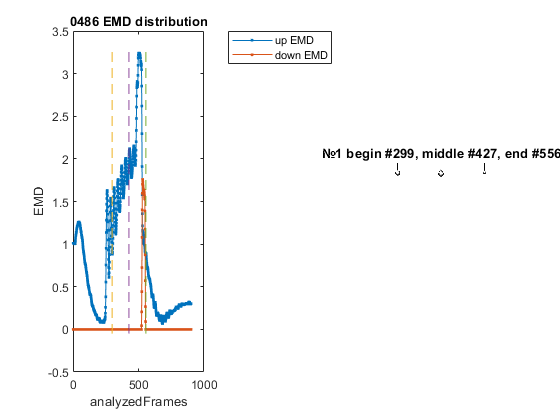

Figure & template were saved


Last row:


    test    video_ranges
    ____    ____________

    486     {'299-556'} 



Saved row:


    {[486]}    {'299-556'}



2) ANALYZING: 0487_photron_avi.avi


Count of detected crops: 2


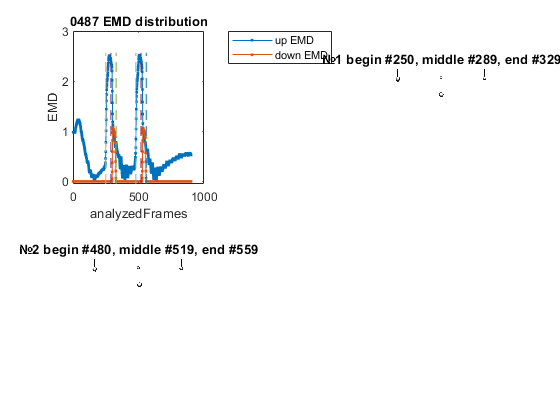

Figure & template were saved


Last row:


    test       video_ranges    
    ____    ___________________

    487     {'250-329,480-559'}



Saved row:


    {[487]}    {'250-329,480-559'}



3) ANALYZING: 0488_photron_avi.avi


Count of detected crops: 2


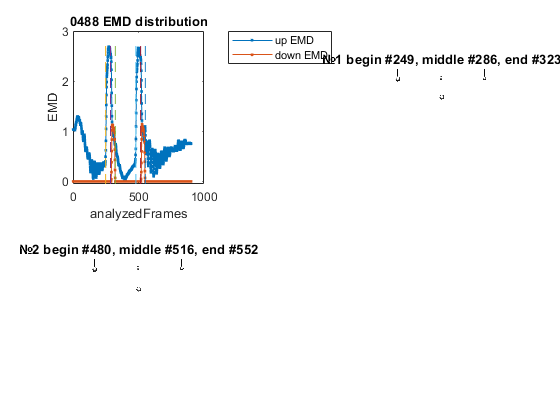

Figure & template were saved


Last row:


Saved row:


    {[488]}    {'249-323,480-552'}



4) ANALYZING: 0489_photron_avi.avi


Count of detected crops: 2


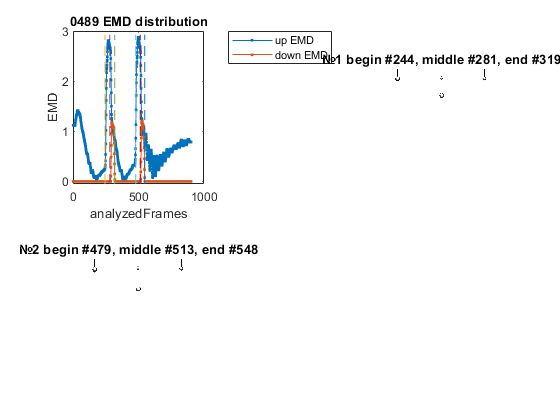

Figure & template were saved


Last row:


Saved row:


    {[489]}    {'244-319,479-548'}



5) ANALYZING: 0490_photron_avi.avi


Count of detected crops: 2


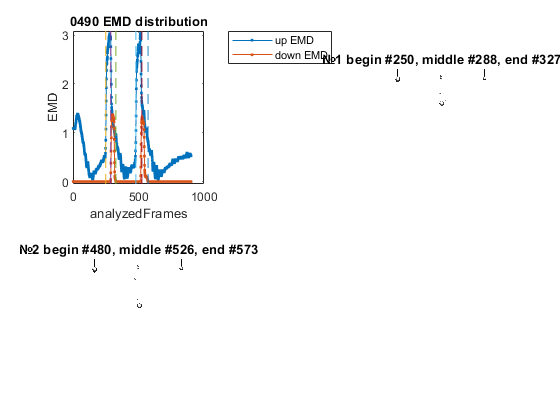

Figure & template were saved


Last row:


Saved row:


    {[490]}    {'250-327,480-573'}



6) ANALYZING: 0491_photron_avi.avi


Count of detected crops: 1


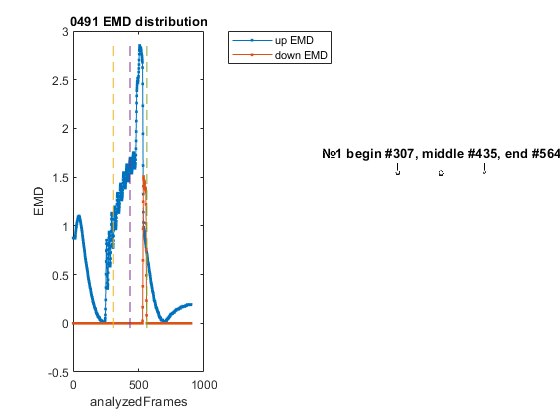

Figure & template were saved


Last row:


Saved row:


    {[491]}    {'307-564'}



7) ANALYZING: 0492_photron_avi.avi


Count of detected crops: 1


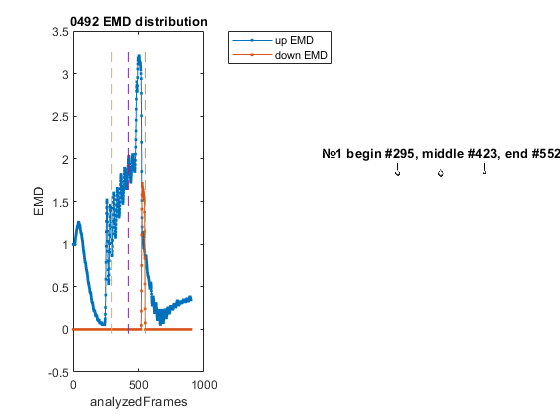

Figure & template were saved


Last row:


Saved row:


    {[492]}    {'295-552'}



8) ANALYZING: 0493_photron_avi.avi


Count of detected crops: 2


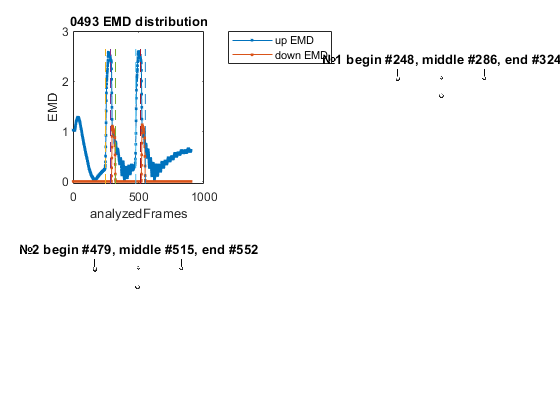

Figure & template were saved


Last row:


Saved row:


    {[493]}    {'248-324,479-552'}



9) ANALYZING: 0494_photron_avi.avi


Count of detected crops: 2


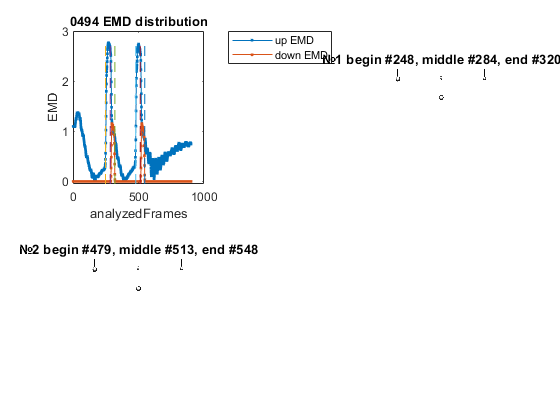

Figure & template were saved


Last row:


Saved row:


    {[494]}    {'248-320,479-548'}



10) ANALYZING: 0495_photron_avi.avi


Count of detected crops: 2


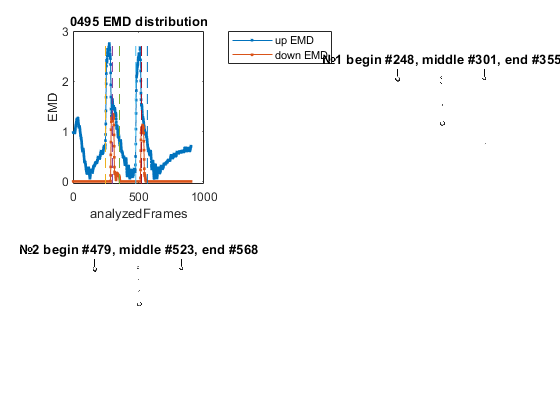

Figure & template were saved


Last row:


Saved row:


    {[495]}    {'248-355,479-568'}



11) ANALYZING: 0496_photron_avi.avi


Count of detected crops: 2


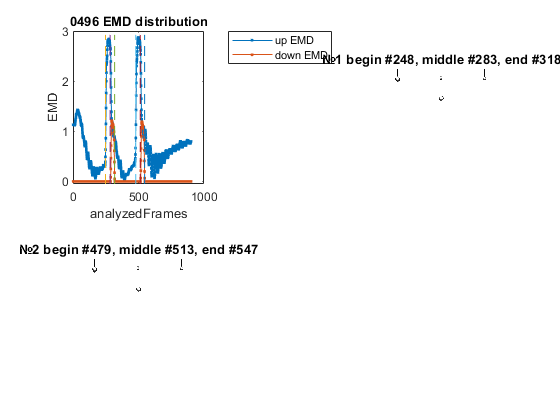

Figure & template were saved


Last row:


Saved row:


    {[496]}    {'248-318,479-547'}



12) ANALYZING: 0497_photron_avi.avi


Count of detected crops: 1


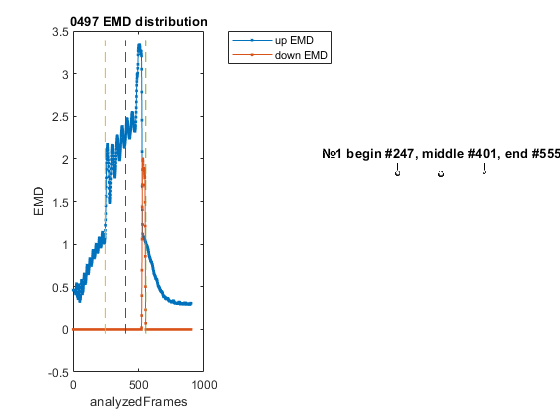

Figure & template were saved


Last row:


Saved row:


    {[497]}    {'247-555'}



13) ANALYZING: 0498_photron_avi.avi


Count of detected crops: 2


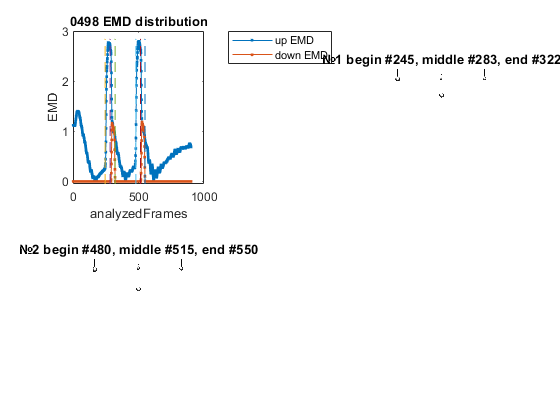

Figure & template were saved


Last row:


Saved row:


    {[498]}    {'245-322,480-550'}



14) ANALYZING: 0499_photron_avi.avi


Count of detected crops: 2


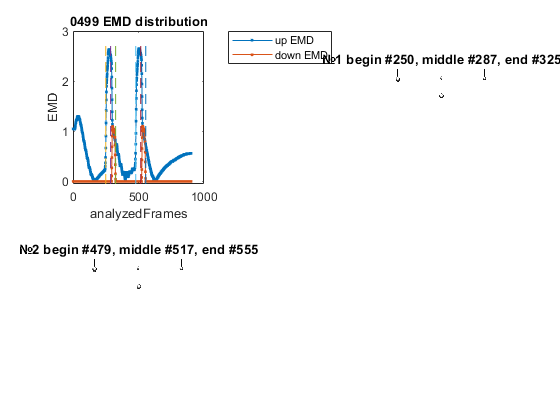

Figure & template were saved


Last row:


Saved row:


    {[499]}    {'250-325,479-555'}



15) ANALYZING: 0500_photron_avi.avi


Count of detected crops: 2


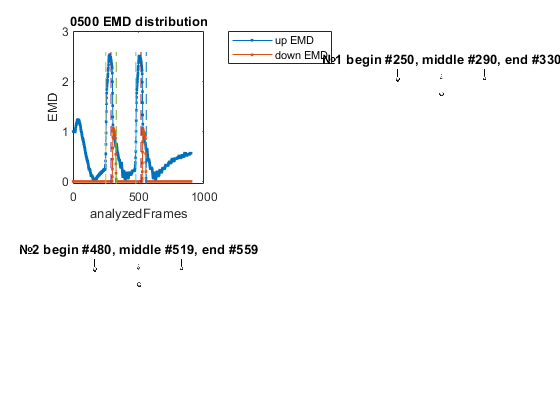

Figure & template were saved


Last row:


Saved row:


    {[500]}    {'250-330,480-559'}



16) ANALYZING: 0501_photron_avi.avi


Count of detected crops: 2


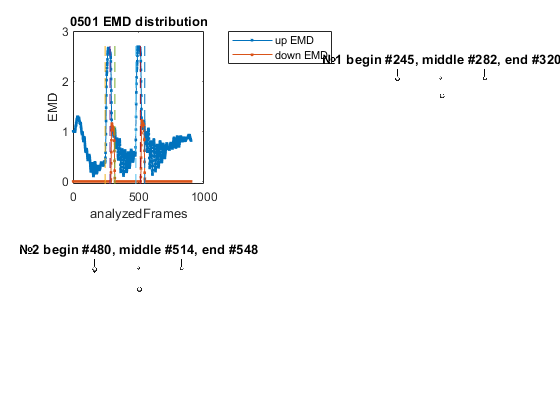

Figure & template were saved


Last row:


Saved row:


    {[501]}    {'245-320,480-548'}



17) ANALYZING: 0502_photron_avi.avi


Count of detected crops: 2


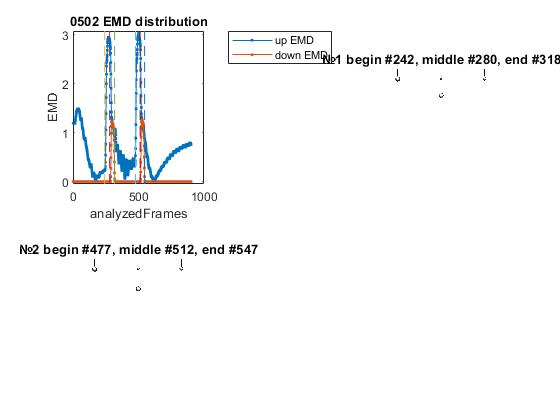

Figure & template were saved


Last row:


Saved row:


    {[502]}    {'242-318,477-547'}



18) ANALYZING: 0503_photron_avi.avi


Count of detected crops: 2


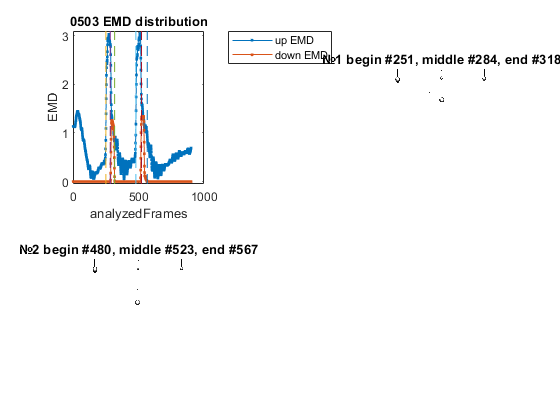

Figure & template were saved


Last row:


Saved row:


    {[503]}    {'251-318,480-567'}



19) ANALYZING: 0504_photron_avi.avi


Count of detected crops: 1


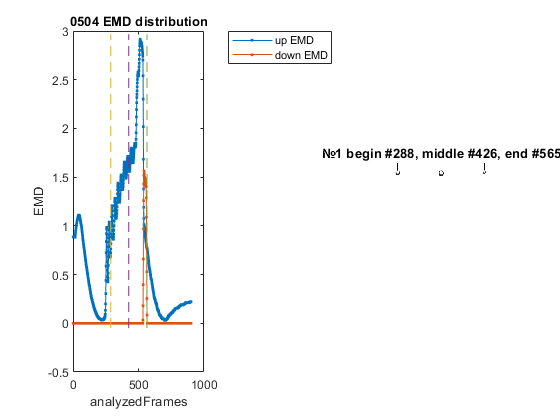

Figure & template were saved


Last row:


Saved row:


    {[504]}    {'288-565'}



20) ANALYZING: 0505_photron_avi.avi


Count of detected crops: 2


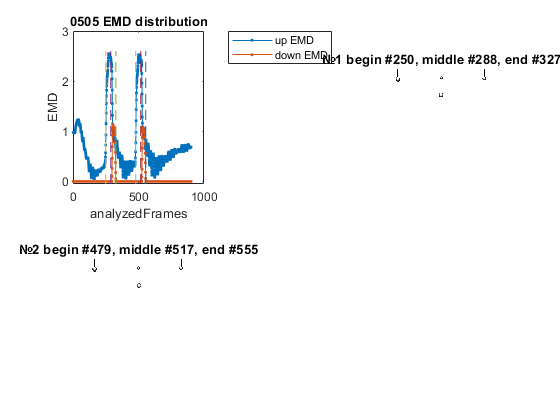

Figure & template were saved


Last row:


Saved row:


    {[505]}    {'250-327,479-555'}



21) ANALYZING: 0506_photron_avi.avi


Count of detected crops: 1


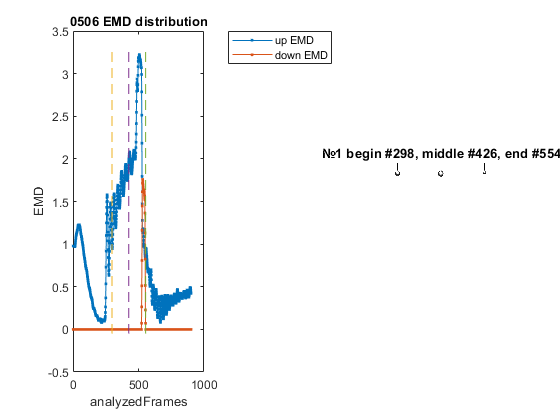

Figure & template were saved


Last row:


Saved row:


    {[506]}    {'298-554'}



22) ANALYZING: 0507_photron_avi.avi


Count of detected crops: 2


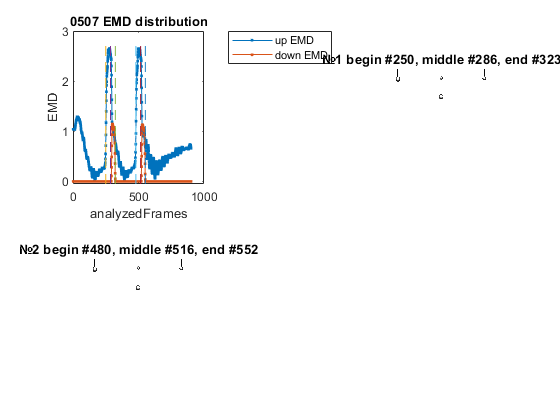

Figure & template were saved


Last row:


Saved row:


    {[507]}    {'250-323,480-552'}



23) ANALYZING: 0508_photron_avi.avi


Count of detected crops: 2


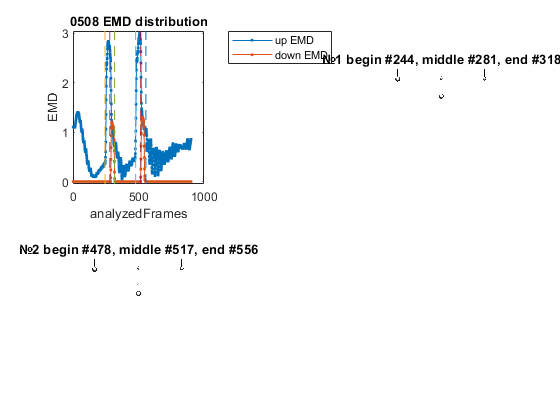

Figure & template were saved


Last row:


Saved row:


    {[508]}    {'244-318,478-556'}



24) ANALYZING: 0509_photron_avi.avi


Count of detected crops: 1


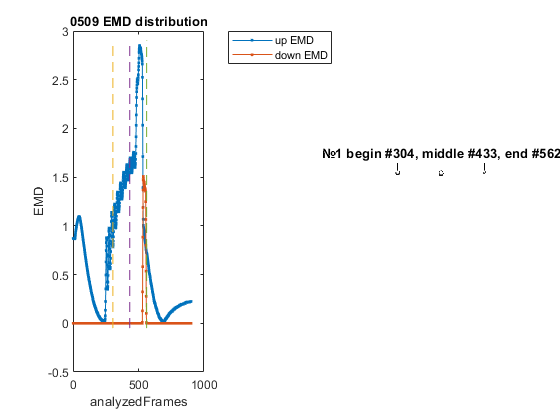

Figure & template were saved


Last row:


Saved row:


    {[509]}    {'304-562'}



25) ANALYZING: 0510_photron_avi.avi


Count of detected crops: 1


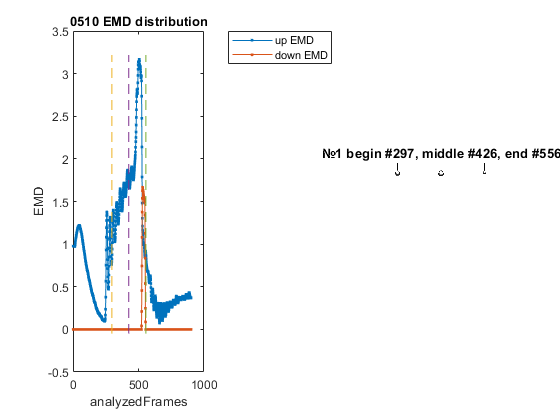

Figure & template were saved


Last row:


Saved row:


    {[510]}    {'297-556'}



26) ANALYZING: 0511_photron_avi.avi


Count of detected crops: 2


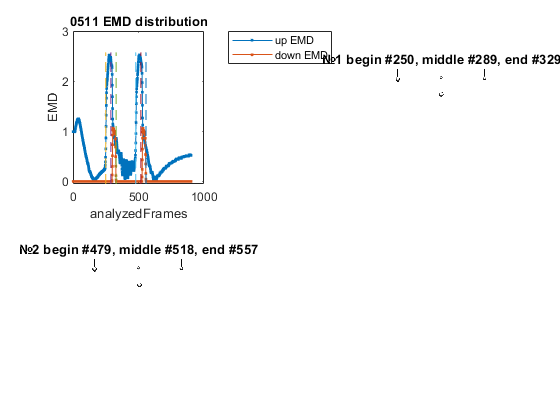

Figure & template were saved


Last row:


Saved row:


    {[511]}    {'250-329,479-557'}



27) ANALYZING: 0512_photron_avi.avi


Count of detected crops: 2


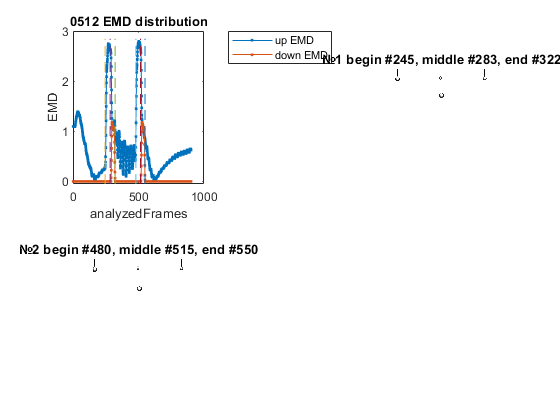

Figure & template were saved


Last row:


Saved row:


    {[512]}    {'245-322,480-550'}



28) ANALYZING: 0513_photron_avi.avi


Count of detected crops: 3


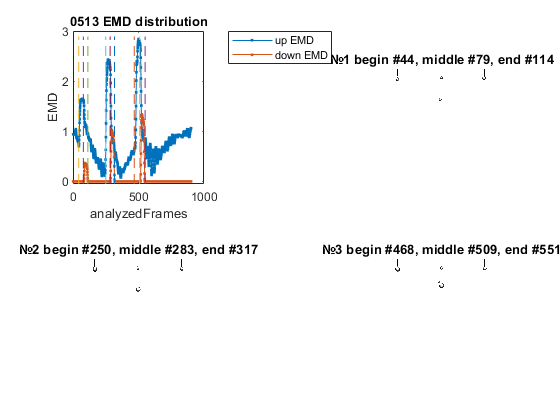

Figure & template were saved


Last row:


Saved row:


    {[513]}    {'44-114,250-317,468-551'}



29) ANALYZING: 0514_photron_avi.avi


Count of detected crops: 2


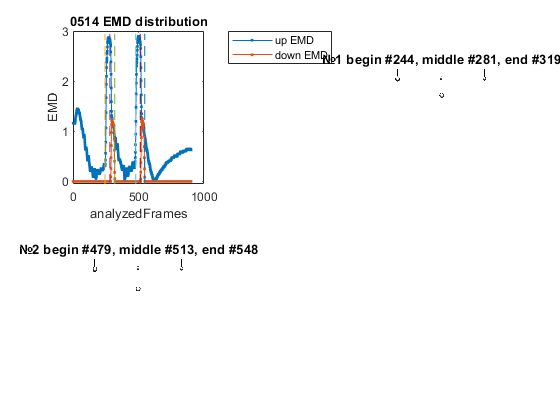

Figure & template were saved


Last row:


Saved row:


    {[514]}    {'244-319,479-548'}



30) ANALYZING: 0515_photron_avi.avi


Count of detected crops: 1


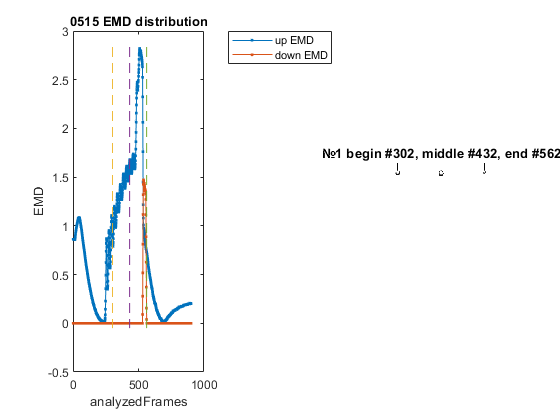

Figure & template were saved


Last row:


Saved row:


    {[515]}    {'302-562'}



31) ANALYZING: 0516_photron_avi.avi


Count of detected crops: 1


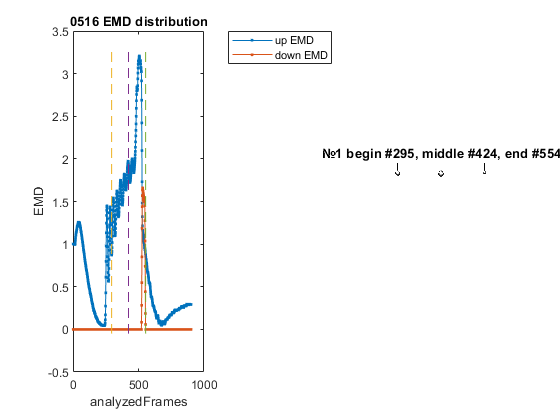

Figure & template were saved


Last row:


Saved row:


    {[516]}    {'295-554'}



32) ANALYZING: 0517_photron_avi.avi


Count of detected crops: 2


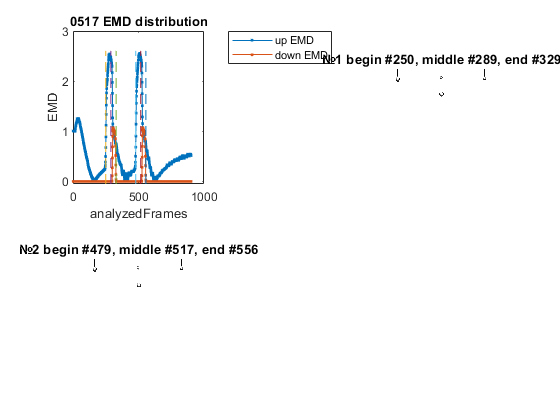

Figure & template were saved


Last row:


Saved row:


    {[517]}    {'250-329,479-556'}



33) ANALYZING: 0518_photron_avi.avi


Count of detected crops: 2


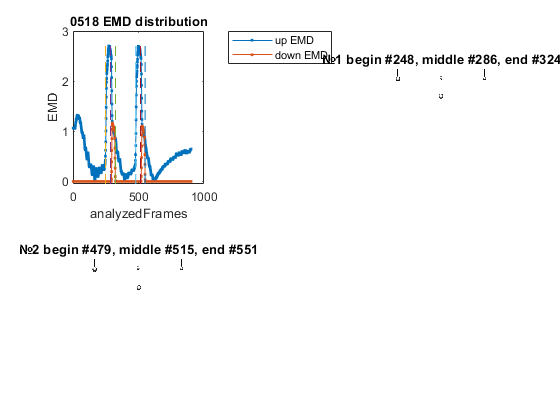

Figure & template were saved


Last row:


Saved row:


    {[518]}    {'248-324,479-551'}



34) ANALYZING: 0519_photron_avi.avi


Count of detected crops: 2


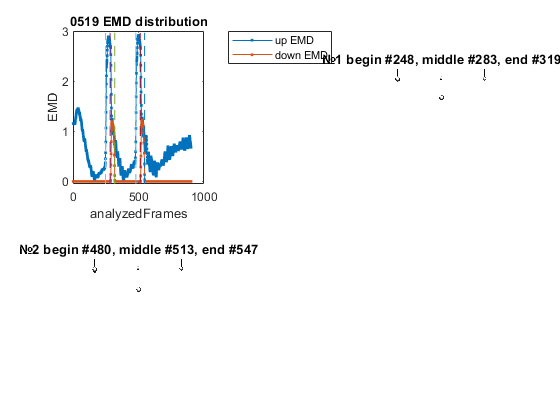

Figure & template were saved


Last row:


Saved row:


    {[519]}    {'248-319,480-547'}



35) ANALYZING: 0520_photron_avi.avi


Count of detected crops: 2


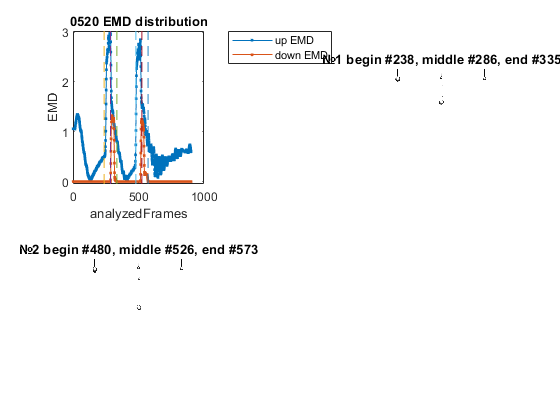

Figure & template were saved


Last row:


Saved row:


    {[520]}    {'238-335,480-573'}




 

%ANALYZE VIDEOS
for cellNum = loadRange(1):loadRange(2) %!!!! parfor cellNum = loadRange(1):loadRange(2)
    currentVideoName = allVideoNames{cellNum};
    if ~isempty(find(contains(analyzeCell, currentVideoName), 1))
        disp(strcat(string(cellNum),") ANALYZING: ", currentVideoName));
     
        obj = allObj{cellNum};
        video = allVideos{cellNum};
        frameRange = [1 allObj{cellNum}.NumFrames];
        
        % current test number
        text = split(currentVideoName,'_');
        testNum = uint16(str2double(text(1)));
    
        % ANALYZE!
        [selectedFrames, analyzedFrames, EMD,...
    templateImg] = cropVideoEMD(obj, video, frameRange, threshold,...
    upScaleKoef, downScaleKoef, frameLimit, smoothSpan, polyOrder,...
    baseFrameSide, maxEMDQuantileValue, maxSecDifQuantileValue,...
    UpDownKoef, quantileThreshold);

        % DISPLAY EMD-Values and images
        figure;
        dispFrames(selectedFrames, analyzedFrames, EMD, video, ...
            testNum);
        % SAVE EMD-Values and images as fig.
        figPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum), ...
            "_EMD",".fig");
        savefig(figPath);
        %close(gcf);
        templPath = strcat(croppingFolderPath, '\',sprintf('%04u',testNum),...
        "_template",".jpg");
        imwrite(templateImg,templPath)
        disp("Figure & template were saved");
        
        % SAVING CROP-RANGE
        
        % Create ranges of crop in string format
        cropRanges = cropRanges2str(selectedFrames);
        
        % READ TABLE
        T = readtable(dataPath);
        
        % delete previos ranges
        toDelete = T.test == testNum;
        lastrow = T(toDelete,:);
        T(toDelete,:) = [];
        % add new value
        savedRow = {testNum,cropRanges};
        T = [T;savedRow];
        
        % WRITE TABLE
        writetable(T,dataPath);
        disp('Last row:');
        disp(lastrow);
        disp('Saved row:');
        disp(savedRow);
    end
end